# Diseño de un sistema de control con observador de estados de orden completo

#### (Ejemplo 1. Control  Tutorials for MATLAB and Simulink)

clear
close all

A = [ 0   1   0
     980  0  -2.8
      0   0  -100 ];

B = [ 0
      0
      100 ];

C = [ 1 0 0 ];

## Prueba de estabilidad del sistema en lazo abierto

poles = eig(A)

poles =    31.3050
  -31.3050
 -100.0000


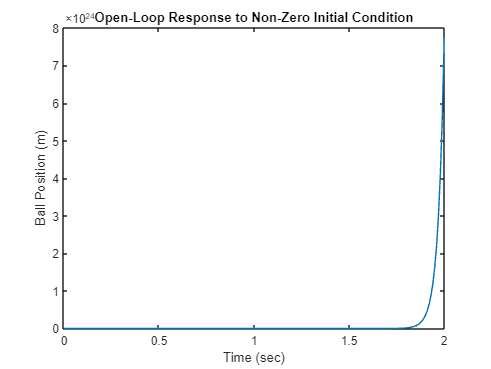

t = 0:0.01:2;
u = zeros(size(t));
x0 = [0.01 0 0];

sys = ss(A,B,C,0);

[y,t,x] = lsim(sys,u,t,x0);
figure(1)
plot(t,y)
title('Open-Loop Response to Non-Zero Initial Condition')
xlabel('Time (sec)')
ylabel('Ball Position (m)')

## Determinación de la matriz de retroalimentación de los estados

p1 = -20 + 20i;
p2 = -20 - 20i;
p3 = -100;


## Simulación de la respuesta del sistema regulador en lazo cerrado

#### (r=0)

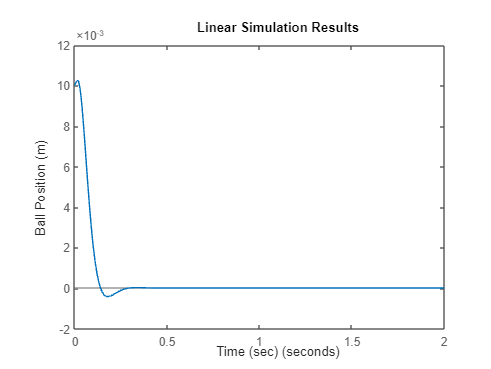

K = place(A,B,[p1 p2 p3]);
sys_cl = ss(A-B*K,B,C,0);
figure(2)
lsim(sys_cl,u,t,x0);
xlabel('Time (sec)')
ylabel('Ball Position (m)')

### Simulación de la respuesta del sistema de control en lazo cerrado

#### (Introduciendo un valor de referencia r=0.001)

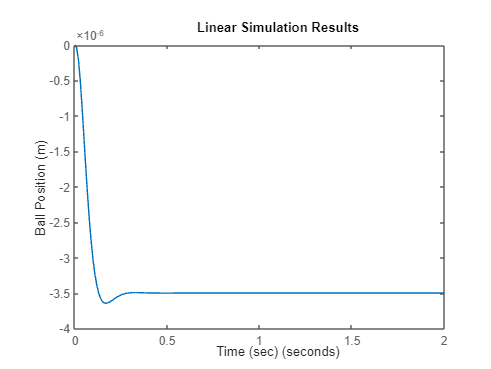

t = 0:0.01:2;
u = 0.001*ones(size(t));

sys_cl = ss(A-B*K,B,C,0);
figure(3)
lsim(sys_cl,u,t)
xlabel('Time (sec)')
ylabel('Ball Position (m)')
axis([0 2 -4E-6 0])

#### Calculo del precompensador Nbar

Nbar = rscale(sys,K)

Nbar = -285.7143

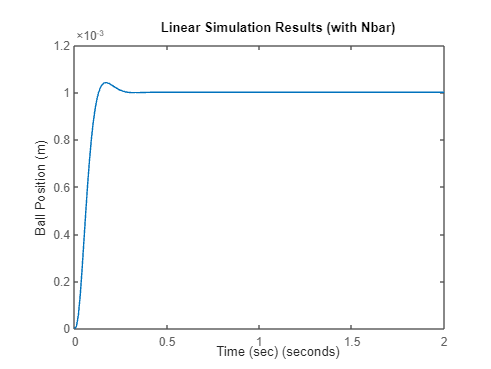

figure(4)
lsim(sys_cl,Nbar*u,t)
title('Linear Simulation Results (with Nbar)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')
axis([0 2 0 1.2*10^-3])

# Diseño de un obervador de estados de orden completo

### Prueba de observabilidad

order(sys)

ans = 3

rank(obsv(sys))

ans = 3

#### Selecciòn de los polos deseados del obervador de estados

op1 = -100;
op2 = -101;
op3 = -102;
Ke = place(A',C',[op1 op2 op3])'

Ke = 1.0e+04 *

    0.0203
    1.1282
         0


% Ecuación 10-70

#### Ecuación 10-70 con entrada( ver archivo ecuacion1070Ogata)

At = [ A-B*K             B*K
       zeros(size(A))    A-Ke*C ];

Bt = [    B*Nbar
       zeros(size(B)) ];

Ct = [ C    zeros(size(C)) ];

### Respuesta a condiciones iniciales (r=0)

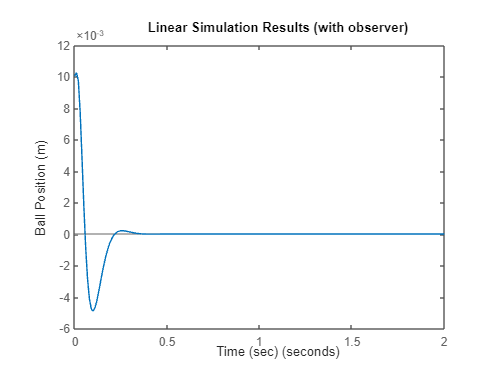

sys = ss(At,Bt,Ct,0);
figure(5)
lsim(sys,zeros(size(t)),t,[x0 x0])
title('Linear Simulation Results (with observer)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')

### Comportamiento de todas las variables de estado  (r=0)

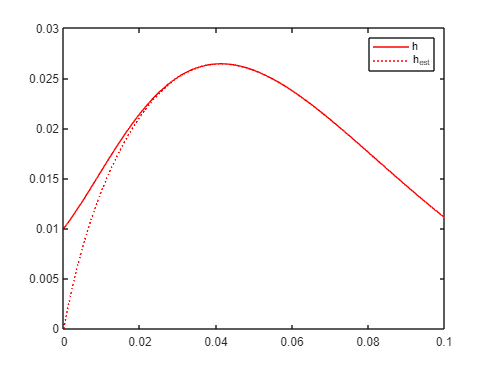

t = 0:1E-6:0.1;
x0 = [0.01 0.5 -5];
[y,t,x] = lsim(sys,zeros(size(t)),t,[x0 x0]);
n = 3;
e = x(:,n+1:end);
x = x(:,1:n);
x_est = x - e;
% Save state variables explicitly to aid in plotting
h = x(:,1); h_dot = x(:,2); i = x(:,3);
h_est = x_est(:,1); h_dot_est = x_est(:,2); i_est = x_est(:,3);
figure(6)
plot(t,h,'-r',t,h_est,':r');
legend('h','h_{est}');

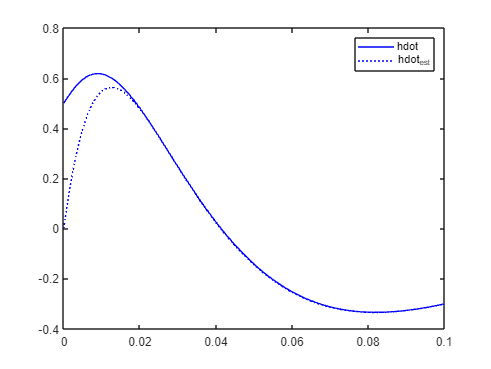

figure(7)
plot(t,h_dot,'-b',t,h_dot_est,':b');
legend('hdot','hdot_{est}');

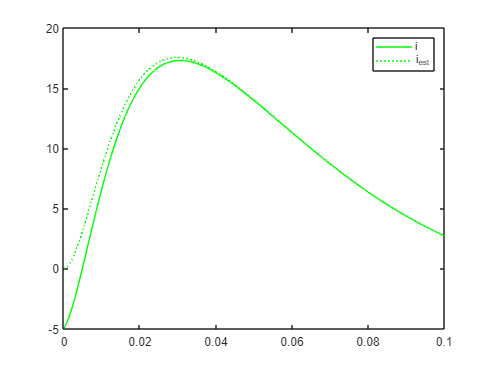


figure(8)
plot(t,i,'-g',t,i_est,':g');
legend('i','i_{est}')

### Respuesta a una referencia diferente de cero (r=0.001)

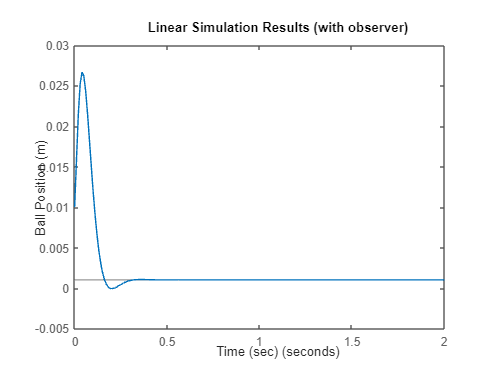

t = 0:0.01:2;
u = 0.001*ones(size(t));
sys = ss(At,Bt,Ct,0);
figure(9)
lsim(sys,u,t,[x0 x0])
title('Linear Simulation Results (with observer)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')

#### Usando el precompensador Nbar para el controlador-observador

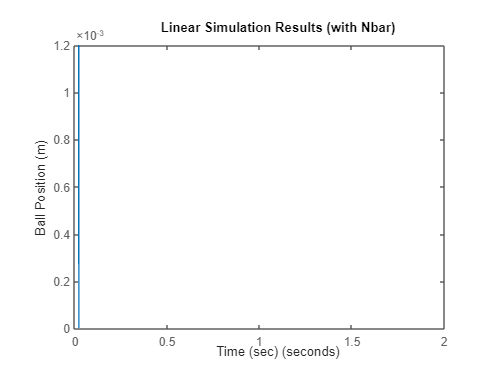

%Nbar = rscale(sys,K)
figure(10)
lsim(sys,Nbar*u,t,[x0 x0])
title('Linear Simulation Results (with Nbar)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')
axis([0 2 0 1.2*10^-3])

### Comportamiento de todas las variables de estado  (r=0.001)

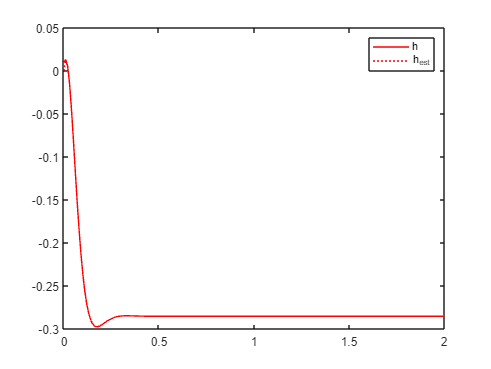

t = 0:0.01:2;
u = 0.001*ones(size(t));
x0 = [0.01 0.5 -5];
[y,t,x] = lsim(sys,Nbar*u,t,[x0 x0]);
n = 3;
e = x(:,n+1:end);
x = x(:,1:n);
x_est = x - e;
% Save state variables explicitly to aid in plotting
h = x(:,1); h_dot = x(:,2); i = x(:,3);
h_est = x_est(:,1); h_dot_est = x_est(:,2); i_est = x_est(:,3);
figure(11)
plot(t,h,'-r',t,h_est,':r');
legend('h','h_{est}');

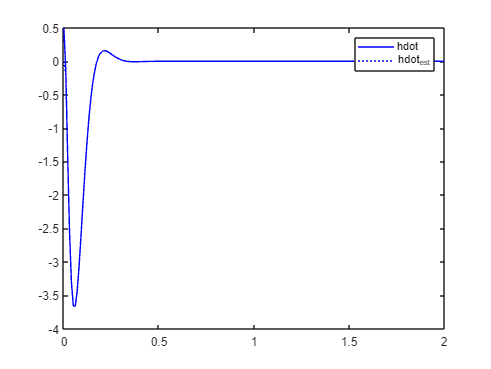

figure(12)
plot(t,h_dot,'-b',t,h_dot_est,':b');
legend('hdot','hdot_{est}');

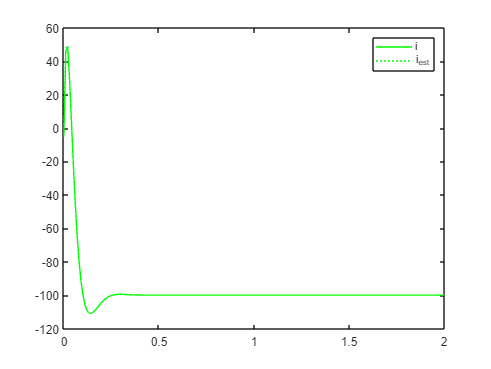


figure(13)
plot(t,i,'-g',t,i_est,':g');
legend('i','i_{est}')